
%script for ploting the indiv rgc morphology
cell_id = 11214;
query = sprintf('cell_unid = %d', cell_id);

data = fetch(sln_image.RetinalCellMorphology & query, '*');

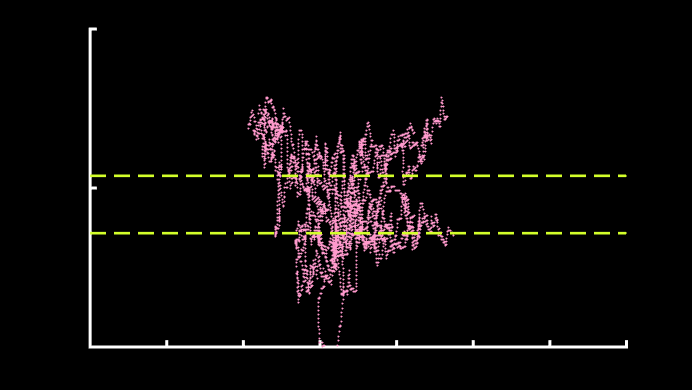

fig = figure();
clf(fig);
hold on;
ax = gca;
fig.Color = 'k';
ax.Color = 'k';
ax.XColor = 'w';
ax.YColor = 'w';
rosepink = [1.00, 0.60, 0.80];
lightcoral = [1, 0.84, 0.31];
limegreen = [211 255 42]/255;
mossgreen = [131, 153, 88]/255;
seinna = [167, 88, 26]/255;

scatter(data.nodes_flattened(:, 1), data.nodes_flattened(:, 3), 1, rosepink,'o','filled');
line([0, 350], ...
    [data.lower_surface_z, data.lower_surface_z], ...
    'Color',limegreen, 'LineStyle', '--', 'LineWidth',1.3);
line([0, 350], ...
    [data.upper_surface_z, data.upper_surface_z], ...
    'Color',limegreen, 'LineStyle', '--', 'LineWidth',1.3);
fig.Position = [100, 100, 800, 450];
ylim([0, 20]);
xlim([0, 350]);
yticks([0, 10, 20]);
xticks(linspace(0, 350, 8));
yticklabels([]);
xticklabels([]);
ax.LineWidth = 1.5;
ax.XAxis.FontSize = 22;
ax.XAxis.FontName = 'Arial';
ax.YAxis.FontSize =22;
ax.YAxis.FontName = 'Arial';
hold off;